# Operations on vertex functions

clear ; close all ; path=pwd();
[s,e]=regexp(path,'.+(?=[\\/]{1,2}examples)');
path=path(s:e); addpath(genpath(path)); clear s e path

## 1) Scalar case

Elementary` VertexFunction `can be combined with others, the computation of the expression and derivative is done automatically.

### a) Some operations

f1s = VertexFunction(@(a) a.^2, @(a) 2*a, "f1s");
f2s = VertexFunction(@(a) a.^3, @(a) 3*a.^2, "f2s");
f3s = VertexFunction(@(a) 0.1*a, @(a) 0.1*ones(size(a)), "f3s");

- Operations with scalars

f1s = f1s*9+pi

f1s =   VertexFunction with properties:

    Expression: @(x)obj1.Expression(x)+obj2
    Derivative: @(x)obj1.Derivative(x)*obj2
      DimInput: 1
     DimOutput: 1
         Label: "9*(f1s)+3.1416"


% 6+9*f1s does not work, the numbers should be placed after the
% VertexFunction

- Operations with other `VertexFunction`

f2s = f1s.*(f2s/3+f3s*2).^(-f2s)

f2s =   VertexFunction with properties:

    Expression: @(x)obj1.Expression(x).*obj2.Expression(x)
    Derivative: @(x)obj1.Derivative(x).*obj2.Expression(x)+obj2.Derivative(x).*obj1.Expression(x)
      DimInput: 1
     DimOutput: 1
         Label: "(9*(f1s)+3.1416).*(((f2s)/3+2*(f3s)).^(-f2s))"


f3s = f1s./f3s

f3s =   VertexFunction with properties:

    Expression: @(x)obj1.Expression(x)./obj2.Expression(x)
    Derivative: @(x)(obj1.Derivative(x).*obj2.Expression(x)-obj2.Derivative(x).*obj1.Expression(x))./((obj2.Expression(x)).^2)
      DimInput: 1
     DimOutput: 1
         Label: "(9*(f1s)+3.1416)./(f3s)"


### b) Interpolation

#### a) Definition of the interpolation domain

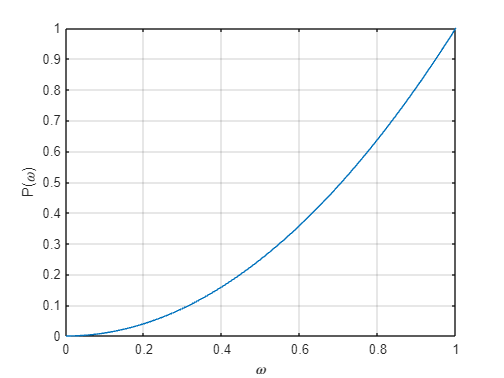

defInterpScalar.Domain = Domain(3);
defInterpScalar.Children = [f1s,f2s,f3s];
defInterpScalar.Label = "interpScalar";
P = Penalization("simp",2);
defInterpScalar.Penalization = P;
P.plot();


interpScalar=Interpolation(defInterpScalar);

#### b) Coordinates of in the polygon

n = 1e3; % number of evaluation points
x = interpScalar.initializeVariable(n,"rand",0.2)

x = struct with fields:
    interpScalar: [1000×2 double]


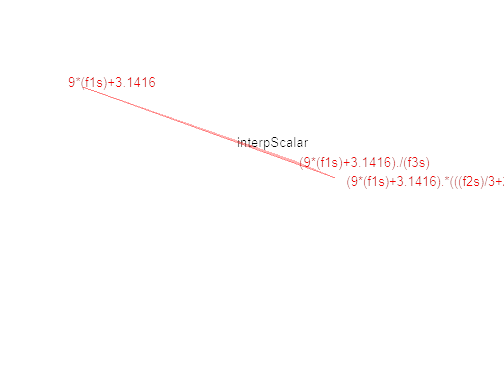

x = interpScalar.projection(x);
figure()
interpScalar.plot(x);

#### c) Evaluation

Each point $x$ is associated to a scalar field value $a$.

a = rand(1,1,n);
[w,dwdx] = interpScalar.evalBasisFunction(x);

tic
val = interpScalar.eval(x,a,w); % value
tv1 = toc;
disp(strcat("Compute interpolated values in ",num2str(tv1*1000)," ms"))

Compute interpolated values in 4.5867 ms



tic
dvalda =  interpScalar.evalda(x,a,w); % derivative w.r.t a
tda1 = toc;
disp(strcat("Compute interpolated a-derivative in ",num2str(tda1*1000)," ms"))

Compute interpolated a-derivative in 7.1898 ms



tic
dvaldx =  interpScalar.evaldx(x,a,w,dwdx); % derivative w.r.t x
tdx1 = toc;
disp(strcat("Compute interpolated x-derivative in ",num2str(tdx1*1000)," ms"))

Compute interpolated x-derivative in 2.1471 ms


#### Check the Taylor expansions

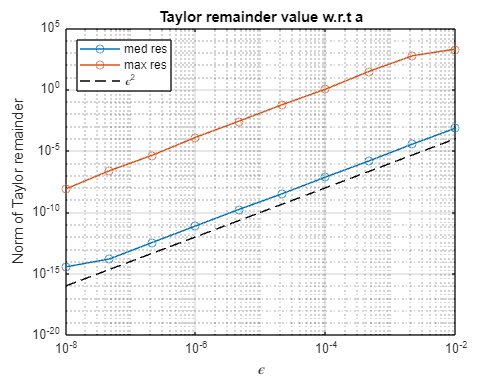

epsilon = logspace(-8,-2,10); % test for different epsilon
res = zeros(10,1,n);

for i=1:10
    pert = epsilon(i)*rand(size(a));
    valPerturbeda = interpScalar.eval(x,a+pert,w);
    res(i,1,:) = vecnorm(valPerturbeda - (val + mult(dvalda,pert)),2,1);
end
MaxRes = max(res,[],3); medRes = median(res,3);
loglog(epsilon,medRes,'-o',epsilon,MaxRes,'-o',epsilon,epsilon.^2,'k--');
legend("med res","max res","\epsilon^2","Location","northwest")
xlabel("\epsilon")
ylabel("Norm of Taylor remainder")
title("Taylor remainder value w.r.t a")
grid on

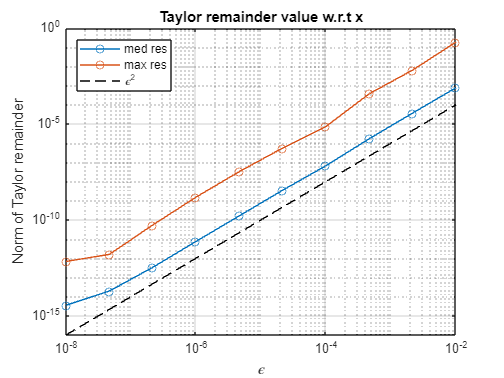


res = zeros(10,1,n);
l = defInterpScalar.Label;

for i=1:10
    pert = epsilon(i)*rand(size(x.(l)));
    xPert.(l) = x.(l) + pert;
    valPerturbedx = interpScalar.eval(xPert,a);
    pert = reshape(pert.',2,1,[]);
    res(i,1,:) = vecnorm(valPerturbedx - (val + mult(dvaldx.(l),pert)),2,1);
end
MaxRes = max(res,[],3); medRes = median(res,3);
loglog(epsilon,medRes,'-o',epsilon,MaxRes,'-o',epsilon,epsilon.^2,'k--');
legend("med res","max res","\epsilon^2","Location","northwest")
xlabel("\epsilon")
ylabel("Norm of Taylor remainder")
title("Taylor remainder value w.r.t x")
grid on

## 2) Vector case

Only inner product is implemented.

dimInput = 2;  dimOutput = 2;
f1v = VertexFunction(@(b) b.^2, @(b) [2*b(1,1,:),zeros(1,1,size(b,3));zeros(1,1,size(b,3)),2*b(2,1,:)], "b.^2", dimInput, dimOutput);
f2v = VertexFunction(@(b) b.^3, @(b)  [3*b(1,1,:).^2,zeros(1,1,size(b,3));zeros(1,1,size(b,3)),3*b(2,1,:).^2], "b.^3", dimInput, dimOutput);

f3v = f1v.innerProduct(f2v)

f3v =   VertexFunction with properties:

    Expression: @(x)mult(t(obj1.Expression(x)),obj2.Expression(x))
    Derivative: @(x)mult(t(obj1.Derivative(x)),obj2.Expression(x))+mult(t(obj2.Derivative(x)),obj1.Expression(x))
      DimInput: 2
     DimOutput: 1
         Label: "<b.^2,b.^3>"


f1v = f3v *2;
f2v = f3v +4;


### b) Interpolation

#### a) Definition of the interpolation domain

defInterpVec.Domain = Domain(3);
defInterpVec.Children = [f1v,f2v,f3v];
defInterpVec.Label = "interpVec";
P = Penalization("simp",2);
defInterpVec.Penalization = P;
P.plot();


interpVec=Interpolation(defInterpVec);

#### b) Coordinates of in the polygon

n = 1e3; % number of evaluation points
x = interpVec.initializeVariable(n,"rand",0.2)

x = struct with fields:
    interpVec: [1000×2 double]


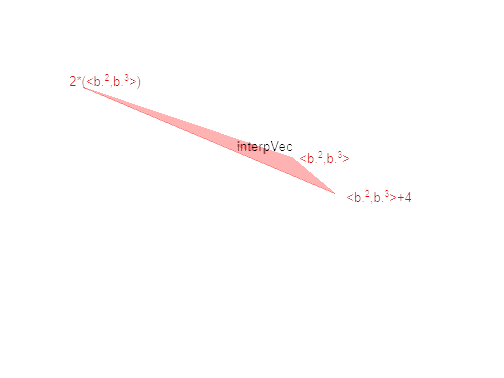

x = interpVec.projection(x);
figure()
interpVec.plot(x);

#### c) Evaluation

Each point $x$ is associated to a vector field value $b$.

b = rand(2,1,n);
[w,dwdx] = interpVec.evalBasisFunction(x);

tic
val = interpVec.eval(x,b,w); % value
tv1 = toc;
disp(strcat("Compute interpolated values in ",num2str(tv1*1000)," ms"))

Compute interpolated values in 2.2414 ms



tic
dvaldb =  interpVec.evalda(x,b,w); % derivative w.r.t a
tda1 = toc;
disp(strcat("Compute interpolated a-derivative in ",num2str(tda1*1000)," ms"))

Compute interpolated a-derivative in 5.6654 ms



tic
dvaldx =  interpVec.evaldx(x,b,w,dwdx); % derivative w.r.t x
tdx1 = toc;
disp(strcat("Compute interpolated x-derivative in ",num2str(tdx1*1000)," ms"))

Compute interpolated x-derivative in 2.2989 ms


#### Check the Taylor expansion

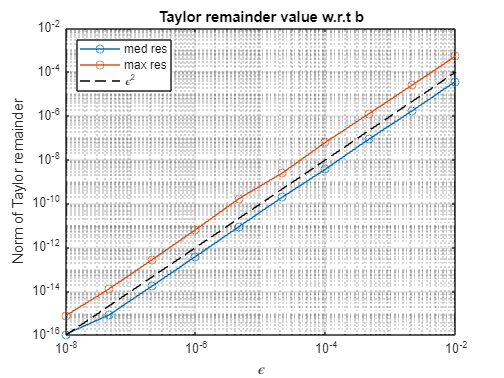

epsilon = logspace(-8,-2,10); % test for different epsilon
res = zeros(10,1,n);
for i=1:10
    bpert = epsilon(i)*rand(size(b));
    valPerturbedb = interpVec.eval(x,b+bpert);
    res(i,1,:) = vecnorm(valPerturbedb - (val + mult(dvaldb,bpert)),2,1);
end
MaxRes = max(res,[],3); medRes = median(res,3);
loglog(epsilon,medRes,'-o',epsilon,MaxRes,'-o',epsilon,epsilon.^2,'k--');
legend("med res","max res","\epsilon^2","Location","northwest")
xlabel("\epsilon")
ylabel("Norm of Taylor remainder")
title("Taylor remainder value w.r.t b")
grid on

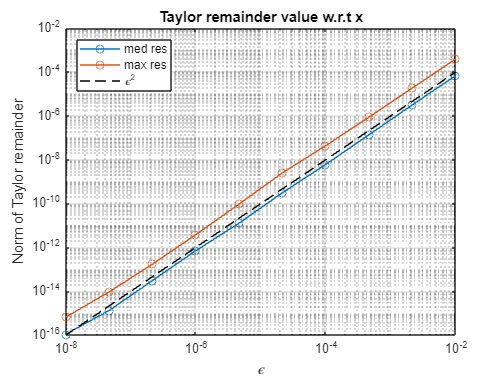



res = zeros(10,1,n);
l = defInterpVec.Label;

for i=1:10
    pert = epsilon(i)*rand(size(x.(l)));
    xPert.(l) = x.(l) + pert;
    valPerturbedx = interpVec.eval(xPert,b);
    pert = reshape(pert.',2,1,[]);
    res(i,1,:) = vecnorm(valPerturbedx - (val + mult(dvaldx.(l),pert)),2,1);
end
MaxRes = max(res,[],3); medRes = median(res,3);
loglog(epsilon,medRes,'-o',epsilon,MaxRes,'-o',epsilon,epsilon.^2,'k--');
legend("med res","max res","\epsilon^2","Location","northwest")
xlabel("\epsilon")
ylabel("Norm of Taylor remainder")
title("Taylor remainder value w.r.t x")
grid on